## Parte 2

    a)

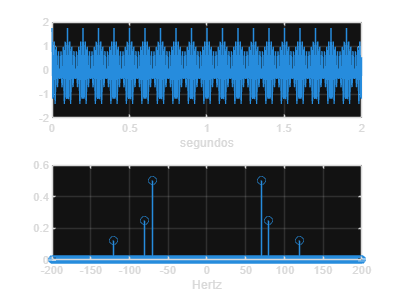

[S,Fa]=exame(911,2);

     b)

N = length(S);
Ta = 1/Fa;

t = (0:N-1)*Ta;
size_t=length(t);
fprintf('O eixo do tempo tem %d amostras', size_t);

O eixo do tempo tem 800 amostras


if rem(N,2) ==0
    f = (-N/2:N/2-1)*(Fa/N);
else
    f =(-(N-1)/2:(N-1)/2)*(Fa/N);
end
size_f=length(f);
fprintf('O eixo da frequência tem %d amostras', size_f);

O eixo da frequência tem 800 amostras

    c)

figure(2);
plot(t,S);

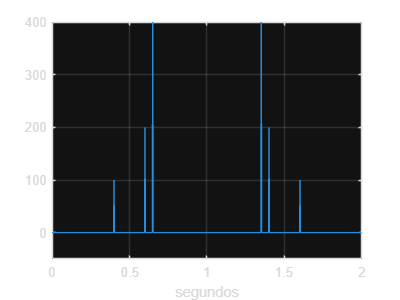

grid on;
xlabel('segundos')

[X,f] = espetro(S,Ta);
subplot(2,1,2);
stem(f,abs(X)/N);
grid on;
xlabel('Hertz')

    d)

N=S(N/2+1);
figure(3);
subplot(2,1,1);

stem(f,abs(X)/N);
grid on;
xlabel('Hertz');
title('Espetro alterado Ex d');
subplot(2,1,2);
[x,t] = reconstroi(abs(X)/N, f);
plot(t,x);

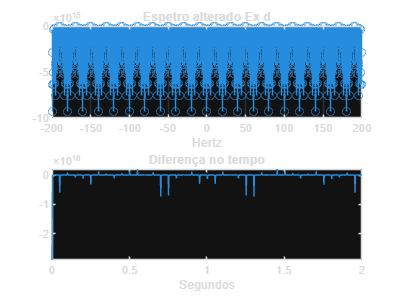

xlabel('Segundos');
title('Diferença no tempo');
%%a amplitude muda
xlim([0,2]);

    e)

figure(4);
subplot(1,1,1);
X_fil = X_limitado(abs(X)/N,f,20,30);
[x1,t1]=reconstroi(X_fil,f);

plot(t1,x1);

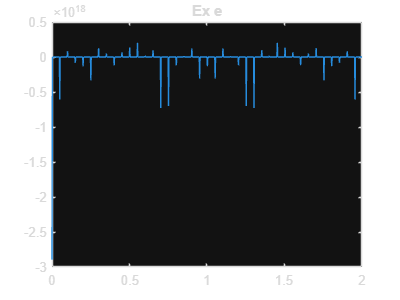

title('Ex e')
xlim([0,2]);